# **El Método de la bisección.**

Primero obvservar la función de manera gráfica y crear la zona en dónde esta la raíz deseada.

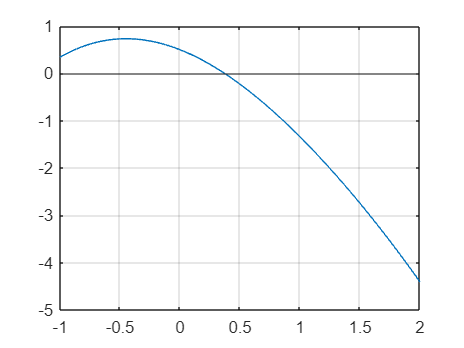

x = linspace(-1,2);
% Aquí puedes cambiar la función para ver tu caso 
y = 0.5 - sin(x) -x.^2;
plot(x,y)
grid on
hold on
yline(0)
hold off

En este paso, debes crear la zona en donde esta la raíz deseada:

% Recuerda que los valores
% deberan cumplir lo siguiente:
%  xp -> f(x) > 0  & xn -> f(x) < 0
xp = -0.5;
xn = 0.8;

Calcula el punto medio:

% xmp == x @ midpoint(mp)
xmp = (xn+xp)/2;
ymp = 0.5 - sin(xmp) - xmp.^2;

Defina el método de la bisección:

for iteration = 1:11
    if ymp < 0
        % ymp es menor que cero
        xn = xmp;
    else ymp > 0
        % ymp es mayor que cero
        xp = xmp;
    end
    xmp = (xn+xp)/2;
    ymp = 0.5 - sin(xmp) -xmp.^2;
end

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


Obvserve los valores  de la raiz

xmp

xmp = 0.3706

ymp

ymp = 5.1258e-04

Gráfique la función y la raíz:

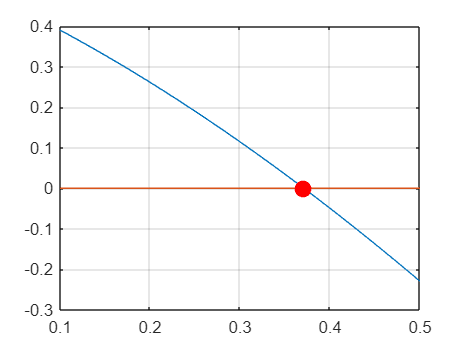

xvals = linspace(0.1,0.5);
yvals = 0.5 - sin(xvals) - xvals.^2;
plot(xvals,yvals)
hold on
plot([0.1 0.5],[0 0])
plot(xmp,ymp,"r.","MarkerSize",30)
hold off
grid on